# Math and Statistics Review for Machine Learning

Summary statistics give valuable insights as one of the first steps in data engineering after the data is gathered. Statistics help to assess data quality and diversity. Data discovery with statistics is a common first activity and there are many excellent built-in MATLAB functions to help with the standard analysis.

We will explore the MATLAB functions that are commonly used for statistical analysis and data exploration. Summary statistics are one of the first steps in data science and machine learning after the data is gathered. It is used to assess data quality and diversity.

## Statistics and Data Visualization

We will import a data set to learn some of the statistics functions and capabilities. 

To import data, use the function "readtable", followed by the location of the data to be read.

data = readtable('http://apmonitor.com/pds/uploads/Main/smallpox.txt');
head(data);

      week       state       state_name         disease       cases    incidence_per_capita
    _________    ______    _______________    ____________    _____    ____________________

    1.928e+05    {'AL'}    {'ALABAMA'    }    {'SMALLPOX'}      1              0.04        
    1.928e+05    {'AR'}    {'ARKANSAS'   }    {'SMALLPOX'}      7              0.38        
    1.928e+05    {'AZ'}    {'ARIZONA'    }    {'SMALLPOX'}      0                 0        
    1.928e+05    {'CA'}    {'CALIFORNIA' }    {'SMALLPOX'}     18              0.34        
    1.928e+05    {'CO'}    {'COLORADO'   }    {'SMALLPOX'}     31              3.06        
    1.928e+05    {'CT'}    {'CONNECTICUT'}    {'SMALLPOX'}     26              1.65        
    1.928e+05    {'DE'}    {'DELAWARE'   }    {'SMALLPOX'} 

### Finding Statistics from a Data Set

Next, use a "Statistics" function to get a quick statistical summary of every column of the data. Have the function iterate for all wanted columns in a data set to give you the mean, standard deviation, min, max, count, and the 1st, 2nd, and 3rd quartiles of the data. An example is shown at the bottom of this script.

statistics(data.week)

ans = struct with fields:
    count: 50916
     mean: 1.9381e+05
      std: 591.4899
      min: 192801
      max: 195250
       Q1: 193312
       Q2: 193819
       Q3: 194324


statistics(data.cases)

ans = struct with fields:
    count: 50916
     mean: 4.5728
      std: 15.0623
      min: 0
      max: 350
       Q1: 0
       Q2: 0
       Q3: 2


statistics(data.incidence_per_capita)

ans = struct with fields:
    count: 50916
     mean: 0.2491
      std: 0.8243
      min: 0
      max: 50.3600
       Q1: 0
       Q2: 0
       Q3: 0.0900


### Visualize the Data

The following will give you some plots to visual the data better.

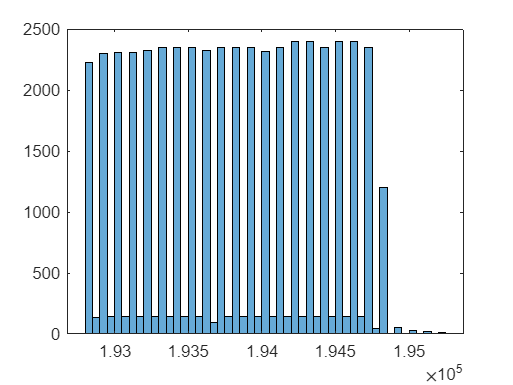

summary_data = summary(data); % Generate a summary of the data

histogram(data.week); % Plot histograms for each variable in the data

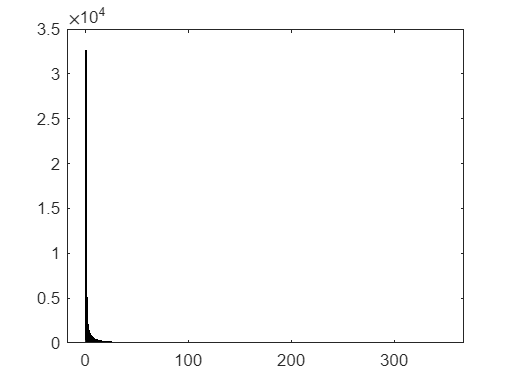

histogram(data.cases);

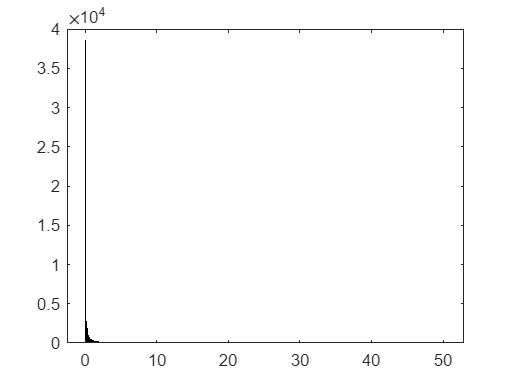

histogram(data.incidence_per_capita);

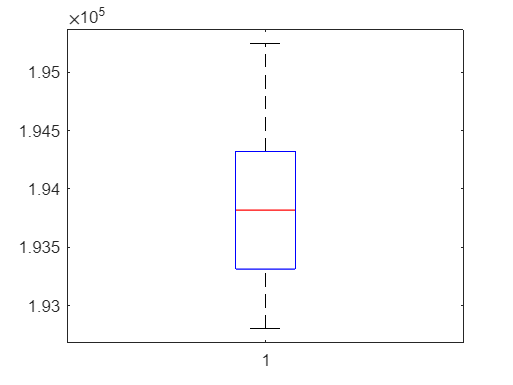


boxplot(data.week); % Plot boxplots for each variable in the data

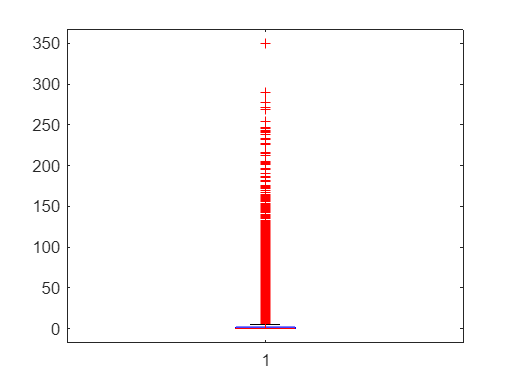

boxplot(data.cases);

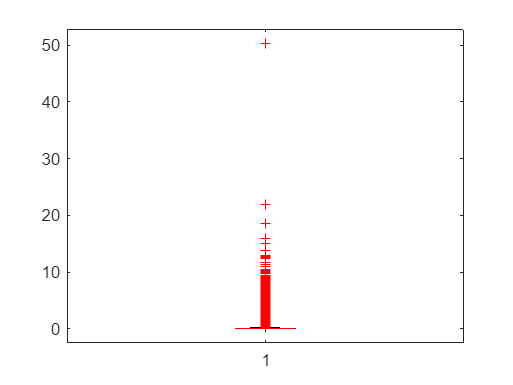

boxplot(data.incidence_per_capita);


% Save the results as an HTML file
current_dir = pwd;
file_path = fullfile(current_dir, 'data.html');

Now you will review and practice some important mathematics and statistics used often for machine learning applications.

## **Mathematics**

**Scalars** are simple numerical values, and are typically denoted by an italicized letter, like *x* or *a*.

**Vectors** are ordered lists of scalar values, and are denoted with bold letters, such as **x** or **w**. The specific attribute of a vector is denoted by a superscript, like so: *w*(j). For example, the vector **w** = [3,2] has the attribute *w*(1) = 3.

**Matrices** are rectangular arrays of numbers arranged in rows or columns, and are denoted with bold capital letters, such as **A** or **W**.

UT = data(strcmp(data.state,'UT'),:);

% Create a matrix containing data from the 'cases' and 'indicence_per_capita' columns
matrix = UT(:,["cases","incidence_per_capita"]);

disp(matrix)
fprintf('Dimensions:%s\n', mat2str(size(matrix)))

Dimensions:[1055 2]


% The vector is composed of the values in the '0' column (first columns) of the matrix
% Use the : to get all valu
% es in the row, and the 0 to get all values in the '0' column
vector = matrix(:,["cases"]);
disp(vector);

    cases
    _____

     19  
     33  
     17  
     19  
     18  
      4  
     22  
     23  
     13  
     13  
     13  
     14  
     18  
     12  
     15  
     10  
     11  
     14  
     12  
     13  
      6  
      1  
      7  
      5  
      3  
     11  
      4  
      4  
      2  
      1  
      0  
      0  
      0  
      0  
      0  
      0  
      1  
      0  
      1  
      0  
     16  
      3  
      1  
      2  
     13  
      1  
      4  
      2  
      3  
      6  
      4  
      6  
     10  
      3  
      5  
      9  
      3  
      4  
      3  
      1  
      5  
      5  
      2  
      4  
      2  
      9  
      7  
     10  
      9  
      6  
      6  
      1  
      5  
      3  
      5  
      7  
     12  
      4  
      4  
      3  
      0  
      3  
      0  
      1  
      2  
      0  
      1  
      0  
      2  
      0  
      1  
      0  
      0  
      0  
     

fprintf('Vector:%s\n', mat2str(size(vector)));

Vector:[1055 1]


fprintf('Dimensions:%s\n', mat2str(size(vector)));

Dimensions:[1055 1]


% Create a scalar out of the 6th attribute of the vector
% MATLAB starts counts with the number 1, so the [6] indicates the 6th value in the array
scalar = table2array(vector(6,:));
fprintf('scalar:%s\n', string(scalar));

scalar:4


fprintf('Dimension:%s\n', mat2str(size(scalar)));

Dimension:[1 1]


### **Activity:**

- Create a matrix **X** out of the 'cases' and 'incidence_per_capita' columns of a state of your choice

- Create a vector **x** containing all the values in the 'incidence_per_capita' column of **X**

- Create a scalar *x*(12) from the 12th value in **x** (remember to use x[11])

- Find the dot product between the 2 distinct vectors in matrix **X**. It may be helpful to import numpy and use np.dot()

It's sometimes useful to sum or multiply all attributes of a vector. The notation for summations over a vector $\mathbf{x}=\left\lbrack x^{\left(1\right)} ,x^{\left(2\right)} ,\ldotp \ldotp \ldotp x^{\left(n-1\right)} ,x^{\left(n\right)} \right\rbrack$ looks like this:


$$\sum_{i=1}^n x^{\left(i\right)} =x^{\left(1\right)} +x^{\left(2\right)} +\ldotp \ldotp \ldotp +x^{\left(n-1\right)} +x^{\left(n\right)}$$


Similarly, the product is summarized using the capital pi notation:


$$\prod_{i=1}^n x^{\left(i\right)} =x^{\left(1\right)} \cdot x^{\left(2\right)} \cdot \ldotp \ldotp \ldotp \cdot x^{\left(n-1\right)} +x^{\left(n\right)}$$


% Find the total number of smallpox cases over all time in Utah
UT_sum = sum(UT{:,["cases"]})

UT_sum = 896

**Activity**: Find the total number of cases in another state.

## Derivatives and Gradients

You should be familiar with analytical derivatives and gradients from calculus courses. While these are most commonly used behind the scenes to solve problems, it's useful to know about these for two reasons. First, you should understand how a numerical derivative works. Second, you may find it beneficial to use the numerical derivative as an additional feature for your machine learning model. You can calculate the numerical derivative as follows:

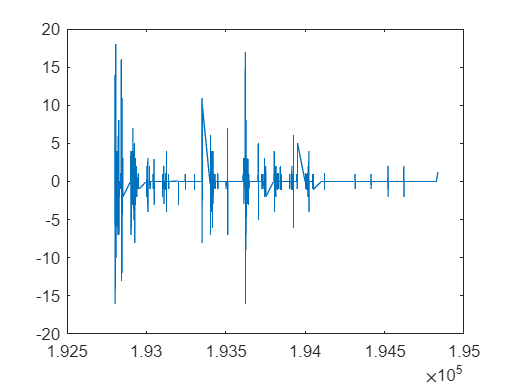

% Be sure the data is sorted according to week
UT = sortrows(UT,"week");

% Find the difference in cases for each consecutive week
UT.('dcases') = diff(vertcat(NaN,UT.cases));


% Find the difference in weeks for each consecutive week should be 1, except for when there are missing weeks
UT.('dweeks') = diff(vertcat(NaN,UT.week));

% Find the numerical derivative, dcases/dweeks
UT.('dcases/dweeks') = UT.('dcases')./UT.('dweeks');

% Plot the numerical derivative
plot(UT.('week'),UT.('dcases/dweeks'));

### **Activity:**

- Find the weekly difference in smallpox cases for your state.

- Calculate the numerical derivative (finite difference) for weekly smallpox cases.

- Plot the numerical derivative for weekly smallpox cases. Interpret the graph.

Repeat the activity by looking at the difference in cases over a time period of 10 weeks. You can use the argument `periods = 10` inside of the `.diff()` function.

## Statistics

### Distributions

The distribution describes the makeup of the data in each column. Distributions can be either discrete (set numbers) or continuous (all numbers in a range are possible). Plotting a distribution allows you not only to see what the data look like, but also to determine if there are suspicious values or if you need to do additional preprocessing.

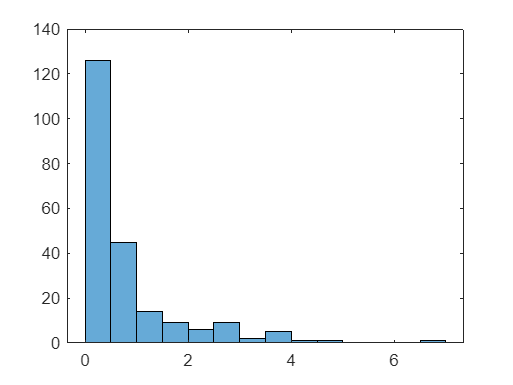

% Plot the distribution of 'incidence_per_capita'; use only non-zero values
histogram(nonzeros(UT.('incidence_per_capita')))

% UT[UT['incidence_per_capita'] != 0]['incidence_per_capita'].hist()

**Activity:**

- Plot the distribution of `'incidence_per_capita'` for your state of choice.

- Sometimes the log scaled values are more useful or give better results. Log scale the `'incidence_per_capita'` and observe the difference.

### Mean and standard deviation

These values are useful in describing a normal distribution. There are also other potentially useful statistical measures (such as kurtosis and skew, which describe deviations from a normal distribution). These statistical measures are not only useful for describing data, but you can potentially use them as features in your machine learning model.

fprintf('All Utah cases')

All Utah cases

statistics(UT.cases)

ans = struct with fields:
    count: 1055
     mean: 0.8493
      std: 2.8168
      min: 0
      max: 33
       Q1: 0
       Q2: 0
       Q3: 0


UT_non0 = nonzeros(UT.('cases'))

UT_non0 =     19
    33
    17
    19
    18
     4
    22
    23
    13
    13


fprintf('Non-zero Utah cases')

Non-zero Utah cases

statistics(UT_non0)

ans = struct with fields:
    count: 216
     mean: 4.1481
      std: 5.0150
      min: 1
      max: 33
       Q1: 1
       Q2: 2
       Q3: 5


**Activity:**

- Display the mean, standard deviation, quartiles, max, and min for the data in another state besides Utah.

- Save the statistics as variables for later use. Use `UT['cases'].mean()`, `.std()`, `.quantile()`, `.max()`, and `.min()`.

- Find the kurtosis and skew of the data. Use `.kurtosis()` and `.skew()`

This is an example of a statistics function to find a summary of common and useful satistics of a set of data.

function statistics = statistics(data)
    statistics.count = numel(data); % count
    statistics.mean = mean(data); % mean
    statistics.std = std(data); % standard deviation
    statistics.min = min(data); % min
    statistics.max = max(data); % max
    statistics.Q1 = prctile(data,25); % 1st quartile (25th percentile)
    statistics.Q2 = prctile(data,50); % 2nd quartile (50th percentile) = median
    statistics.Q3 = prctile(data,75); % 3rd quartile (75th percentile)
end

